**COT 5930 Image processing, spring 2021  -- Christian Garbin**

# Assignment 5: Image classification

Code in this live script was created based on the starter code. All unattributed text and code should be assumed to be from the starter code. All  mistakes an dpoorly written pieces of code are mine.

## Dataset

Create the dataset, backed by images on disk, adpated through an imageDatastore.

categories = {'cat', 'dog'};
numClasses = 2;

[trainingSet, validationSet] = getDataset( ...
    './data/PetImages', categories, 0.7, true);

## Experiment 1 - AlexNet transfer learning

Reuse (freeze) all layers, but the last three. This is where the classificaiton happens, so we need to adapt it to our case, where we have two classes (cats and dogs).

model = alexNextTransferLearning(numClasses);

Configuration

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...

Dataset distribution before rebalancing: cat=20, dog=20
Dataset distribution after rebalancing: cat=20, dog=20
Training set distribution: cat=14, dog=14
Validation set distribution: cat=6, dog=6


    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

Retrain the network

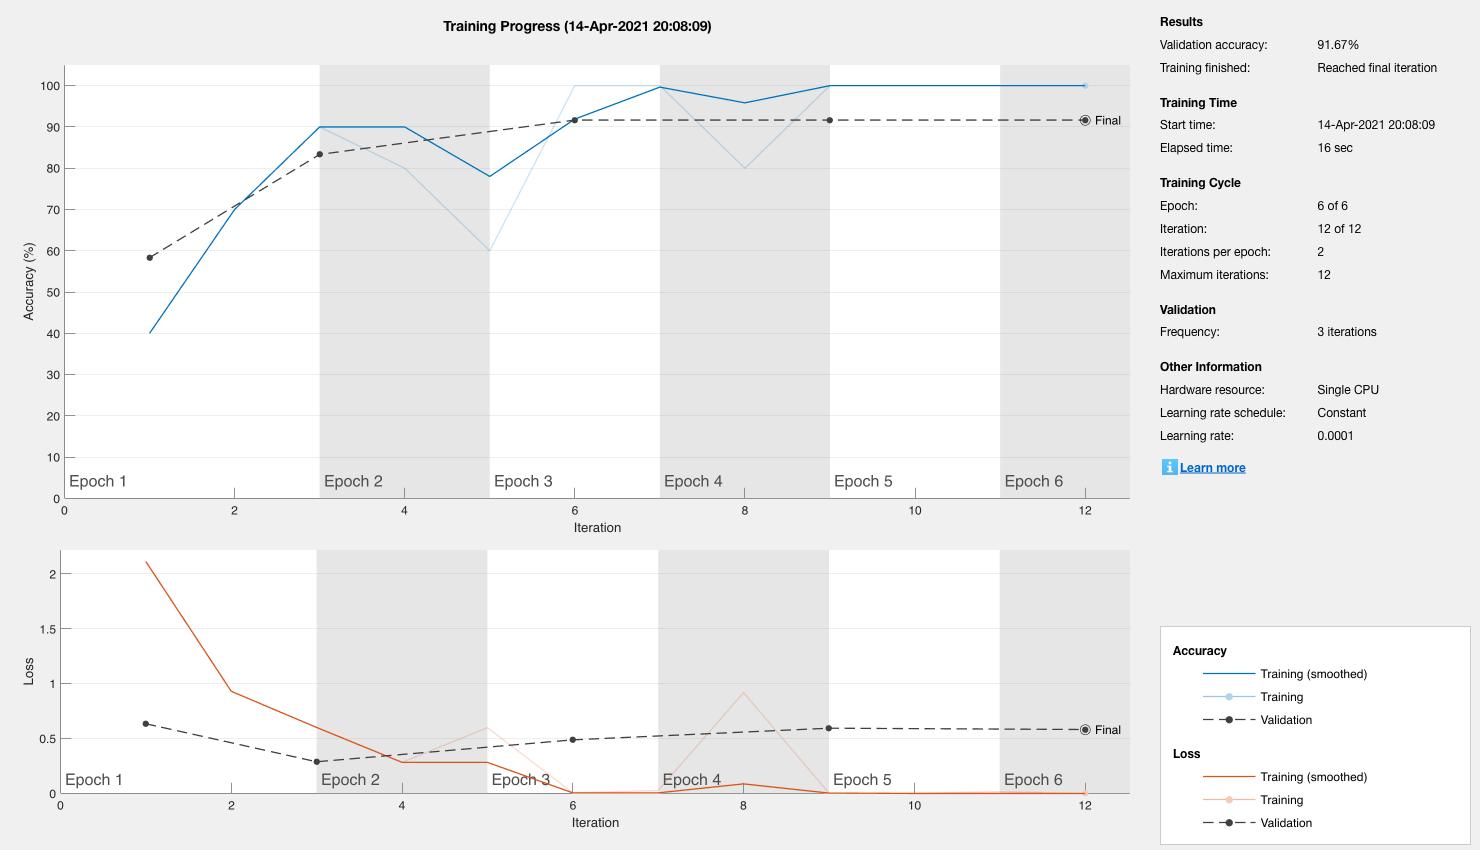

modelTransfer = trainNetwork(trainingSet,model,options);

Predict scores on the validation set and calculate accuracy.

[YPred,scores] = classify(modelTransfer,validationSet);

YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 91.67 %


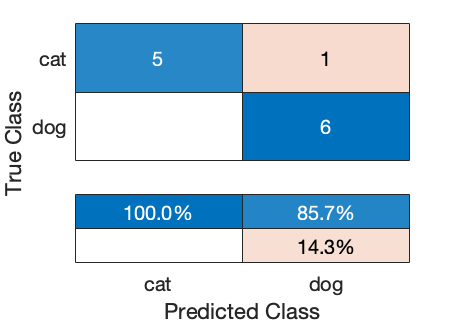

confusionchart(YValidation,YPred, "ColumnSummary","column-normalized")

### Predict specific images

Predicted: dog, confidence: 99.998367%

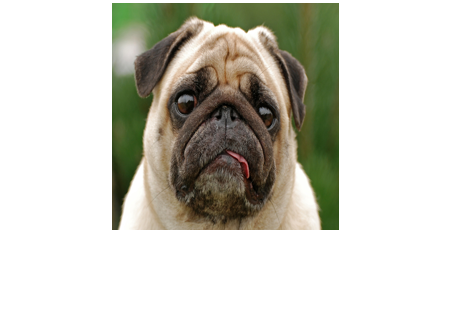

predictAndShow('./dog.jpg',modelTransfer,categories)

Predicted: cat, confidence: 100.000000%

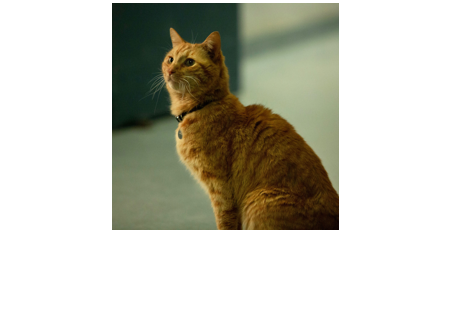

predictAndShow('./cat.jpg',modelTransfer,categories)

## Data augmentation

imageAugmentation object.

% In our case, we shall use an augmented image datastore to randomly flip
% the training images along the vertical axis and randomly translate them
% up to 30 pixels and scale them up to 10% horizontally and vertically.
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

Augmented training and validation sets.

inputSize = model.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations)

    14




augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

disp(augimdsValidation.NumObservations)

     6



## Retrain with augmented data

miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

modelAug = trainNetwork(augimdsTrain,layers,options);

Predict scores on the validation set and calculate accuracy.

[YPredAug,probsAug] = classify(modelAug,augimdsValidation);

YValidationAug = validationSet.Labels;
accuracyAug = mean(YPredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug * 100);

The validation accuracy is: 50.00 %


## Auxiliary functions

### Dataset

Create a dataset backed by an image store. The function assumes there are only two categories and that the directory structure is correctly split into these categories (the name of the directories mus match the name of the categories for the `imageDatastore` to work correctly).

function [trainingSet, validationSet] = getDataset( ...
    dataFolder, categories, trainPercentage, verbose)

    function showStats(text, imds)
        if verbose
            tempTbl = countEachLabel(imds);
            fprintf("%s: %s=%d, %s=%d\n", text, ...
                tempTbl(1,1).Label, tempTbl(1,2).Count, ...
                tempTbl(2,1).Label, tempTbl(2,2).Count)
        end
    end

    imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');
    showStats('Dataset distribution before rebalancing', imds)
   
    % Ensure the categories are balanced by using the smallest overlap set (may not be
    % needed for some datasets, but protects in case we use an unbalanced dataset
    % without realizing it).
    tbl = countEachLabel(imds);
    minSetCount = min(tbl{:,2});
    % Trim the set.
    imds = splitEachLabel(imds, minSetCount, 'randomize');
    % Each set must now have exactly the same number of images.
    showStats('Dataset distribution after rebalancing', imds)
    
    % AlexNet can only process RGB images that are 227-by-227
    % To avoid re-saving all the images to this format, setup the |imds| read function,
    % |imds.ReadFcn|, to pre-process images on-the-fly. The |imds.ReadFcn| is called
    % every time an image is read from the |ImageDatastore|
    imds.ReadFcn = @(filename)readAndPreprocessImage(filename);
    
    [trainingSet, validationSet] = splitEachLabel(imds, trainPercentage, 'randomized');
    showStats('Training set distribution', trainingSet)
    showStats('Validation set distribution', validationSet)
end

Show an image and its prediction.

function predictAndShow(file, model, categories)
    image = file;
    image = readAndPreprocessImage(image);

    pred = predict(model, image);
    [confidence,idx] = max(pred);
    fprintf("Predicted: %s, confidence: %f%%", ...
        categories{idx}, 100*confidence)

    figure
    imshow(image)
    drawnow
end

### Model

Create an AlexNet model ready for transfer learning.

function model = alexNextTransferLearning(numClasses)
    originalModel = alexnet;
    
    layersTransfer = originalModel.Layers(1:end-3);

    model = [
        layersTransfer
        fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
        softmaxLayer
        classificationLayer];
end